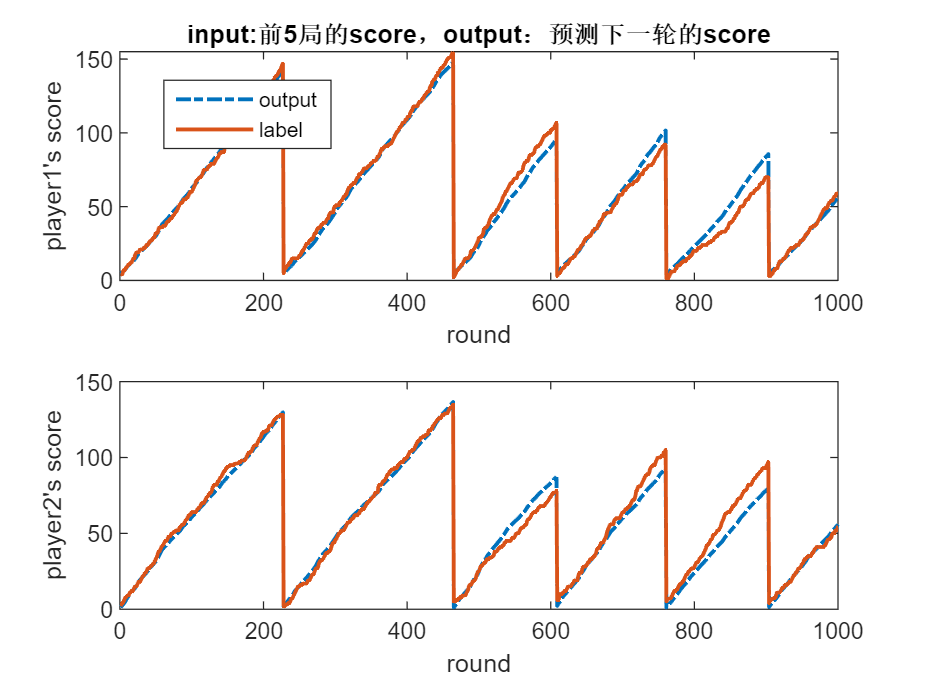

clc,clear
load test_out.mat
% out = round(reshape(test_out(:,1,:),1000,2));
out = reshape(test_out(:,1,:),1000,2);
label = reshape(test_labels(:,1,:),1000,2);
figure
subplot(2,1,1)
plot(out(:,1),'-.','LineWidth',1.5)
hold on
plot(label(:,1),'-','LineWidth',1.5)
legend('output','label')
legend("Position",[0.1784,0.78705,0.17772,0.096446])
ylabel("player1's score")
xlabel("round")
title("input:前5局的score，output：预测下一轮的score")
subplot(2,1,2)
plot(out(:,2),'-.','LineWidth',1.5)
hold on
plot(label(:,2),'-','LineWidth',1.5)
legend('output','label')
legend("Position",[0.1784,0.78705,0.17772,0.096446])
ylabel("player2's score")
xlabel("round")

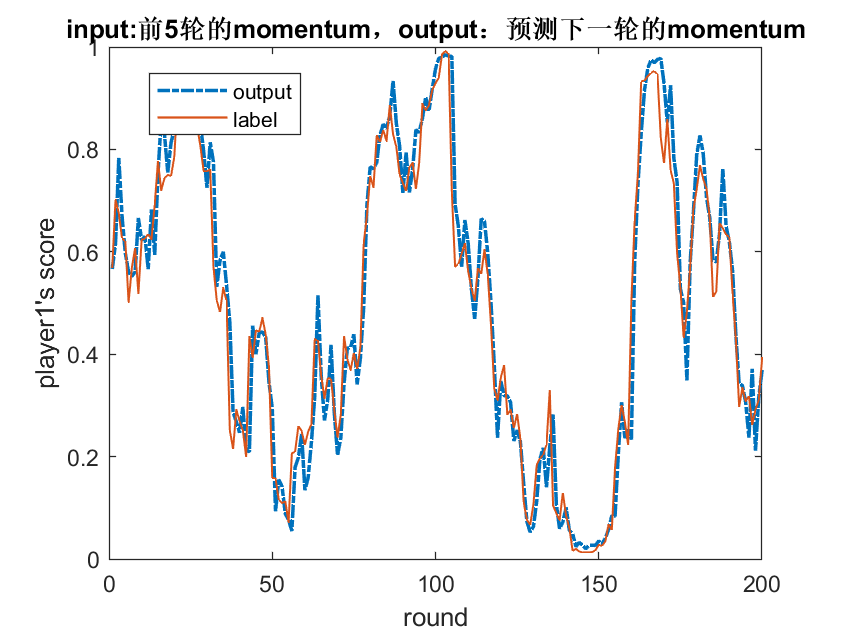

clc,clear
output_len = 888;
load test_out_m.mat
out = reshape(test_out(:,1,:),output_len,2);
label = reshape(test_labels(:,1,:),output_len,2);
figure
% subplot(2,1,1)
plot(out(:,1),'-.','LineWidth',1.5)
hold on
plot(label(:,1),'-','LineWidth',1)
legend('output','label')
legend("Position",[0.1784,0.78705,0.17772,0.096446])
ylabel("player1's score")
xlabel("round")
title("input:前5轮的momentum，output：预测下一轮的momentum")
xlim([0,200])

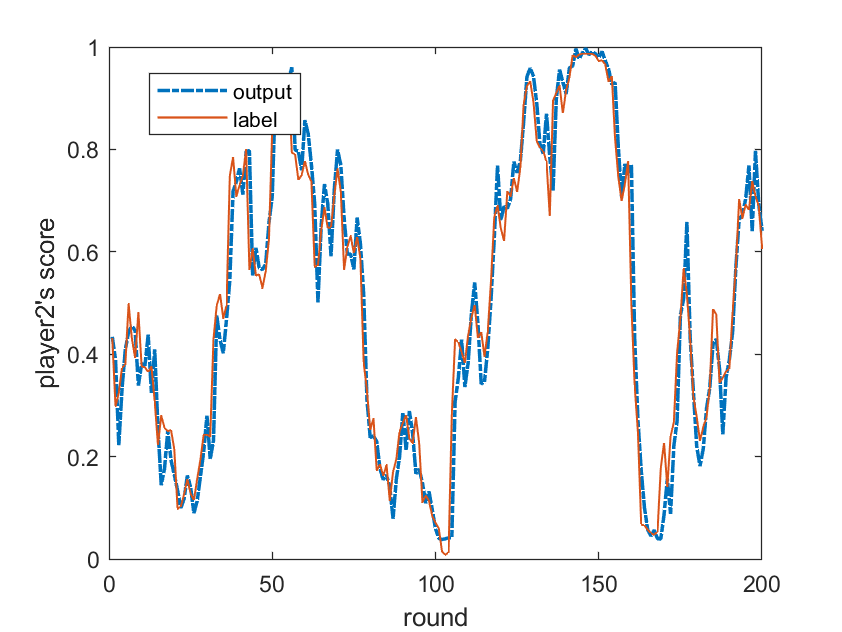

% subplot(2,1,2)
figure
plot(out(:,2),'-.','LineWidth',1.5)
hold on
plot(label(:,2),'-','LineWidth',1)
legend('output','label')
legend("Position",[0.1784,0.78705,0.17772,0.096446])
ylabel("player2's score")
xlabel("round")
xlim([0,200])